### **Projekt: Situation Understanding**

## **Implementierung eines Extended Kalman Filters für die Positionsschätzung eines aufsteigenden Helikopters. **

Für diese Projekt wird ein Helikopter, welcher von dem Boden aus aufsteigt, simuliert. Der Helikopter fliegt dabei in einer Art spirale. Die Bewegungsgleichung dieses Helikopters wird in dem folgenden Codeabschnitt definiert. Um den Helikopter mit Sensnoren zu erfassen, werden zwei Radarsensoren definiert, welche die Bewegungen des Helikopters mit Polarkoordinaten messen.

% Initialisierung der Zustandsvariablen
R_0 = [0; 0; 0];  % Anfangsposition (Nullvektor)
V_0 = [0; 0; 0];  % Anfangsgeschwindigkeit (Nullvektor)

% Zeitbereich auf eine Minute erweitern
t = linspace(0, 120, 240);

% Beschleunigung in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
A = [1 * cos(t/12); 0.5 * sin(t/12); 0.05 * ones(size(t/12))];

% Geschwindigkeit in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
V = cumtrapz(t/12, A, 2) + V_0;

% Position in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
R_pos = R_0 + cumtrapz(t/12, V, 2) + 0.5 * cumtrapz(t/12, A, 2) .* t;

% Anzahl der Zeitschritte
N = length(t);

% Radarpositionen
pos_radar1 = [0, -10, 0];
pos_radar2 = [-50, 30, 0];

% Zustandsvektor x_k (6-dimensional: [x, y, z, vx, vy, vz])
x_k = [R_pos(1,:); R_pos(2,:); R_pos(3,:); V(1,:); V(2,:); V(3,:)];


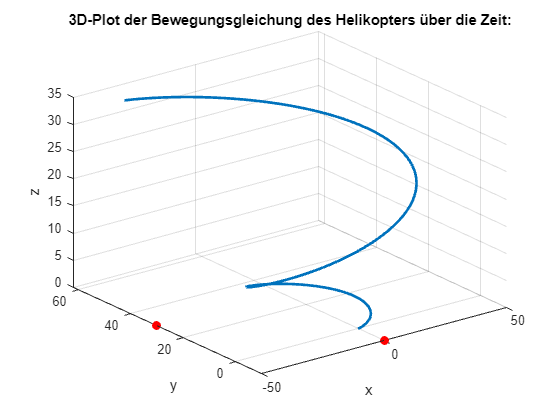

figure;
hold on;  % Aktiviert den "hold on"-Modus, um mehrere Plots in derselben Figur zu zeichnen
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);  % Zeichnet den 3D-Plot der Daten R mit Linienbreite 2

% Zeichnet den Punkt für Radar 1 in Rot mit einem Marker der Größe 20
plot3(pos_radar1(1), pos_radar1(2), pos_radar1(3), 'r.', 'MarkerSize', 20);
% Zeichnet den Punkt für Radar 2 in Rot mit einem Marker der Größe 20
plot3(pos_radar2(1), pos_radar2(2), pos_radar2(3), 'r.', 'MarkerSize', 20);
title('3D-Plot der Bewegungsgleichung des Helikopters über die Zeit:');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;
view(3);
hold off;

% Prozessrauschkovarianzmatrix Q        (Annahme: Prozessrauschen ist 0, da wir noch keine weiteren Informationen haben)
Q = eye(6) * 0.1;

% Messrauschkovarianzmatrix R (Annahme: gleiche Varianzen für alle Beobachtungen)
standardabweichung_x = 0.7;  % Standardabweichung in x-Richtung
standardabweichung_y = 0.7;  % Standardabweichung in y-Richtung
standardabweichung_z = 0.7;  % Standardabweichung in z-Richtung

R = diag([standardabweichung_x^2, standardabweichung_y^2, standardabweichung_z^2, ...
          standardabweichung_x^2, standardabweichung_y^2, standardabweichung_z^2]);



% Zustandsübergangsmatrix F (Identity matrix as we assume constant velocity)
% Zeitschrittgröße
dt = t(2) - t(1);

% Zustandsübergangsmatrix F
F = [1 0    2.5*dt^2      2*dt^2      dt          2*dt;
     0 1    0           0.5*dt      0.125*dt^2    0;
     0 0    1           0.25*dt^2    0           0;
     0 0    0           1           0           0;
     0 0    0           0           1           0.5*dt^2;
     0 0    0           0           0           1]; 

% Schätzung der Anfangsvarianz des Zustandsvektors (Annahme: großer Wert, da wir wenig über den Anfangszustand wissen)
P = 1*eye(6);

z_m = [];
x_m = [];
% messungen erstellen
for i = 2:N
        
        % Es gibt ein Rauschen bei den Radarmessungen welches in x,y,z Richtung jeweils um +/- 0.5 Meter ausmachen kann.
        % Das Rauschen ist dabei für beiden Sensoren das Gleiche.
        zufallswerte_x = rand(1, 1) - 0.5;
        zufallswerte_y = rand(1, 1) - 0.5;
        zufallswerte_z = rand(1, 1) - 0.5;
        
        % Scale and shift the values to the range between -0.25 and 0.25
        zufallswerte_x = zufallswerte_x * standardabweichung_x;
        zufallswerte_y = zufallswerte_y * standardabweichung_y;
        zufallswerte_z = zufallswerte_z * standardabweichung_z;

        x_x2 = x_k(1,i) + zufallswerte_x;
        x_y2 = x_k(2,i) + zufallswerte_y;
        x_z2 = x_k(3,i) + zufallswerte_z;
        x_x1 = x_k(1,i) + zufallswerte_x;
        x_y1 = x_k(2,i) + zufallswerte_y;
        x_z1 = x_k(3,i) + zufallswerte_z;
        x_noise = [x_x1; x_y1;x_z1;x_x2;x_y2;x_z2];
        x_noise2 = [x_x2;x_y2;x_z2];
        %z = [calculate_observations(x_k(:, i), pos_radar1); calculate_observations(x_k(:, i), pos_radar2)];
        z = [calculate_observations(x_noise, pos_radar1); calculate_observations(x_noise2, pos_radar2)];
        z_m = [z_m, z];
    
end
z_m

z_m =     9.7613   10.3232    9.7885    9.7503    9.8059   10.0576   10.3731   10.0589   10.4433   10.0482   10.2917   10.5895   10.6372   10.3240   10.8567   10.4337   11.0931   10.8634   11.5846   11.2189   11.8004   12.2972   12.4732   12.4825   13.2064   13.5324   13.6816   14.1881   14.5647   15.1316   15.3095   15.8475   16.3668   16.9949   17.3407   17.6576   18.1477   18.5520   18.8606   19.2721   19.9898   20.0258   20.6440   21.0131   21.7121   21.9915   22.5585   22.7764   23.0302   23.6537
   88.5877   91.4115   87.5340   89.5602   87.0172   87.0646   85.6230   86.0305   83.8882   83.8445   82.6203   79.9121   78.2001   78.7950   78.4832   75.7376   75.4554   73.6464   72.6214   70.5712   69.5342   67.1443   64.0043   63.6437   62.4858   62.2338   59.9651   59.0245   58.7482   58.4841   57.6097   57.2739   55.6517   55.6607   55.9159   55.3501   55.1201   55.4298   55.4319   54.0098   55.3120   55.4647   54.1798   56.5099   55.5736   57.1600   56.5007   57.1947   57.2286   

**Geschätze Position im Vergleich zur tatsächlichen Position:**

messung_kartesisch = get_kartesische_Koordianten(z_m);


% Plot der geschätzten Position in 3D-Raum
figure(1);
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot3(messung_kartesisch(1, :), messung_kartesisch(2, :), messung_kartesisch(3, :), 'r.', 'MarkerSize', 7);
plot3(pos_radar1(1), pos_radar1(2), pos_radar1(3), 'r.', 'MarkerSize', 20);
plot3(pos_radar2(1), pos_radar2(2), pos_radar2(3), 'r.', 'MarkerSize', 20);
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des ersten Radars:');
xlabel('x');
ylabel('y');
zlabel('z');
view()

ans =     0.7934   -0.6088         0   -0.0923
    0.3044    0.3967    0.8660   -0.7835
    0.5272    0.6871   -0.5000    8.3031
         0         0         0    1.0000


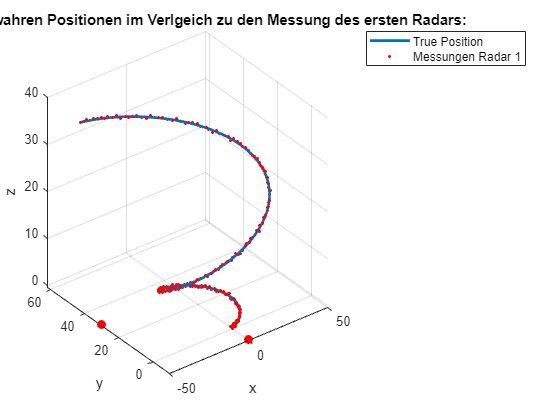

grid on;
view(3);
hold off;
legend('True Position','Messungen Radar 1');


% Plot der geschätzten Position in 3D-Raum
figure(1);
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot3(messung_kartesisch(4, :), messung_kartesisch(5, :), messung_kartesisch(6, :), 'g.', 'MarkerSize', 7);
plot3(pos_radar1(1), pos_radar1(2), pos_radar1(3), 'r.', 'MarkerSize', 20);
plot3(pos_radar2(1), pos_radar2(2), pos_radar2(3), 'r.', 'MarkerSize', 20);
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des zweiten Radars:');
xlabel('x');
ylabel('y');
zlabel('z');
view()

ans =     0.7934   -0.6088         0   -0.0923
    0.3044    0.3967    0.8660   -0.7835
    0.5272    0.6871   -0.5000    8.3031
         0         0         0    1.0000


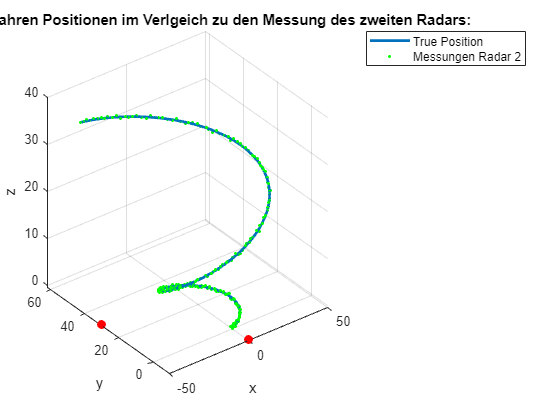

grid on;
view(3);
hold off;
legend('True Position','Messungen Radar 2');

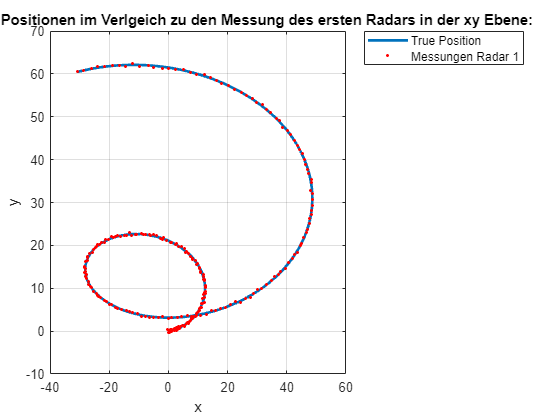



% Plot der geschätzten Position in 3D-Raum
figure(1);
plot(R_pos(1,:), R_pos(2,:), 'LineWidth', 2);
hold on;
plot(messung_kartesisch(1, :), messung_kartesisch(2, :), 'r.', 'MarkerSize', 7);
hold off;
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des ersten Radars in der xy Ebene:');
xlabel('x');
ylabel('y');
grid on;
legend('True Position','Messungen Radar 1');

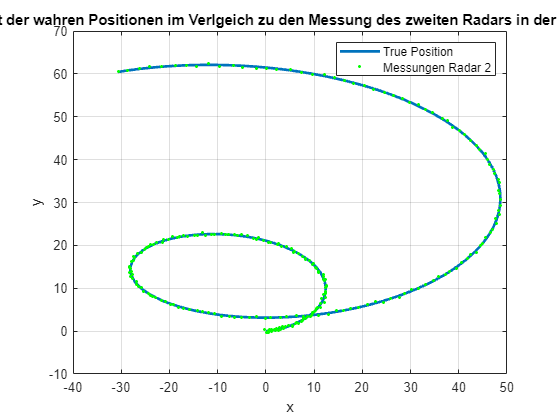


% Plot der geschätzten Position in 3D-Raum
figure(1);
plot(R_pos(1,:), R_pos(2,:), 'LineWidth', 2);
hold on;
plot(messung_kartesisch(4, :), messung_kartesisch(5, :), 'g.', 'MarkerSize', 7);
hold off;
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des zweiten Radars in der xy Ebene:');
xlabel('x');
ylabel('y');
grid on;
legend('True Position','Messungen Radar 2');

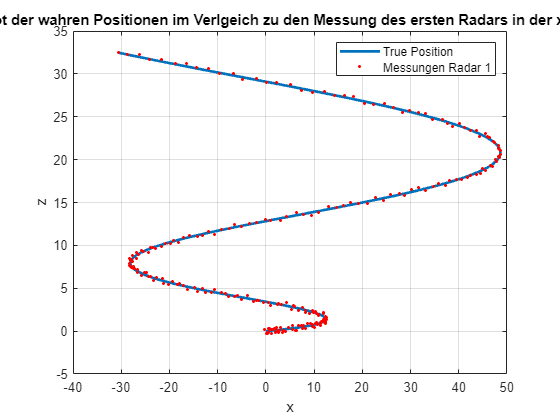



figure(1);
plot(R_pos(1,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot(messung_kartesisch(1, :), messung_kartesisch(3, :), 'r.', 'MarkerSize', 7);
hold off;
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des ersten Radars in der xz Ebene:');
xlabel('x');
ylabel('z');
grid on;
legend('True Position','Messungen Radar 1');

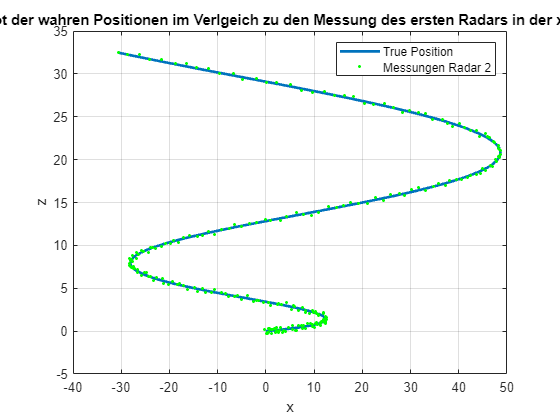


figure(1);
plot(R_pos(1,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot(messung_kartesisch(4, :), messung_kartesisch(6, :), 'g.', 'MarkerSize', 7);
hold off;
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des ersten Radars in der xz Ebene:');
xlabel('x');
ylabel('z');
grid on;
legend('True Position','Messungen Radar 2');

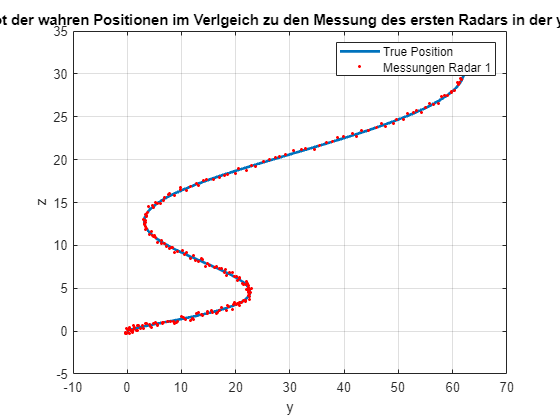




figure(1);
plot(R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot(messung_kartesisch(2, :), messung_kartesisch(3, :), 'r.', 'MarkerSize', 7);
hold off;
xlabel('y');
ylabel('z');
grid on;
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des ersten Radars in der yz Ebene:');
legend('True Position','Messungen Radar 1');

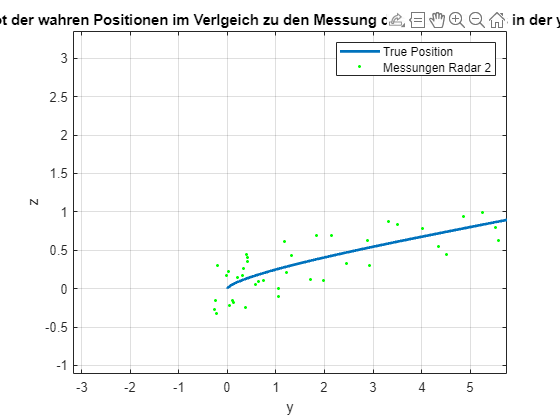


figure(1);
plot(R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot(messung_kartesisch(5, :), messung_kartesisch(6, :), 'g.', 'MarkerSize', 7);
hold off;
xlabel('y');
ylabel('z');
grid on;
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des ersten Radars in der yz Ebene:');
legend('True Position','Messungen Radar 2');

% EKF-Schätzung
for k = 2:N
    % Vorhersage
    x_k_pred = F * x_k(:, k-1);
    P_pred = F * P * F' + Q;
    % Update (Kalman Gain)
    H = create_observation_matrix(x_k_pred, pos_radar1, pos_radar2);
    K = P_pred * H' * inv(H * P_pred * H' + R);
    
    % Messungen
    %z_k = [calculate_observations(x_k(:, k), pos_radar1); calculate_observations(x_k(:, k), pos_radar2)];
    z_k = z_m(:,k-1);

    messungen = [messungen, z_k];
    % Update der Zustandsschätzung und Fehlerkovarianz
    x_k(:, k) = x_k_pred + K * (z_k - [calculate_observations(x_k_pred, pos_radar1); calculate_observations(x_k_pred, pos_radar2)]);
    P = (eye(6) - K * H) * P_pred;
end

% Geschätzte Position des Helikopters
estimated_position = x_k(1:3, :)

estimated_position =          0    0.4101   -0.8938    1.5903   -0.8803    1.2483    0.1602    0.9249    0.5906    1.2940    0.9863    1.4121    1.8638    2.1483    2.0472    2.0586    2.8448    2.5716    3.1436    3.3482    3.8468    4.0449    4.6640    5.4996    5.5291    6.0290    6.2563    6.8416    7.2258    7.5239    7.7946    8.2245    8.4776    9.1082    9.4856    9.7380   10.0965   10.3557   10.5016   10.6961   11.2648   11.3488   11.4507   11.9584   11.7067   12.0701   11.9875   12.3349   12.4230   12.5177
         0   -0.1512    0.1110    0.1533    0.2184    0.0985    0.1845    0.2734    0.2313    0.3052    0.2375    0.2309    0.3268    0.3906    0.3348    0.5501    0.2889    0.6473    0.5329    0.8566    0.7368    0.9867    1.2027    1.2005    1.3662    1.6001    1.9364    1.9388    2.1491    2.4089    2.8128    2.9475    3.3008    3.4837    3.9145    4.3019    4.5307    4.8739    5.2527    5.5293    5.6263    6.2387    6.5110    6.7382    7.3634    7.8193    8.3575    8.75

% Funktion zur Berechnung der Beobachtungen (Messmodell)

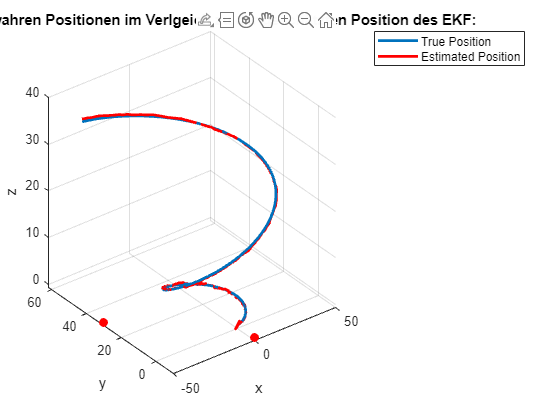

% Plot der geschätzten Position in 3D-Raum
figure(1);
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot3(estimated_position(1, :), estimated_position(2, :), estimated_position(3, :), 'r', 'LineWidth', 2);
plot3(pos_radar1(1), pos_radar1(2), pos_radar1(3), 'r.', 'MarkerSize', 20);
plot3(pos_radar2(1), pos_radar2(2), pos_radar2(3), 'r.', 'MarkerSize', 20);
hold off;
title('3D-Plot der wahren Positionen im Verlgeich zu der geschätzten Position des EKF:');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;
legend('True Position', 'Estimated Position');

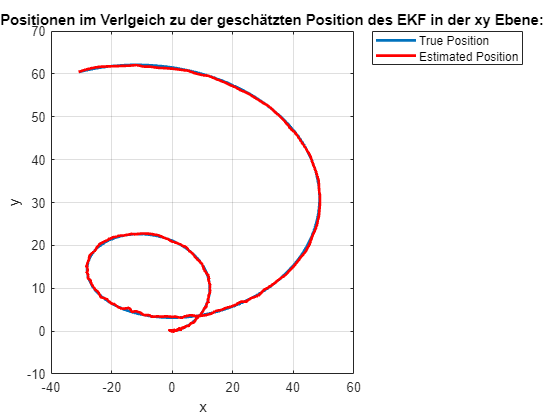


% Plot der geschätzten Position in 3D-Raum
figure(1);
plot(R_pos(1,:), R_pos(2,:), 'LineWidth', 2);
hold on;
plot(estimated_position(1, :), estimated_position(2, :), 'r', 'LineWidth', 2);
hold off;
title('3D-Plot der wahren Positionen im Verlgeich zu der geschätzten Position des EKF in der xy Ebene:');
xlabel('x');
ylabel('y');
grid on;
legend('True Position', 'Estimated Position');

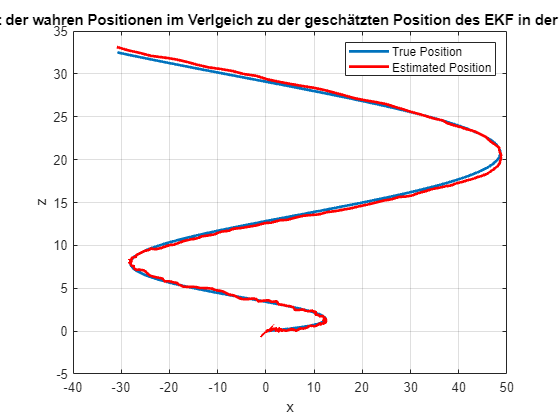


figure(1);
plot(R_pos(1,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot(estimated_position(1, :), estimated_position(3, :), 'r', 'LineWidth', 2);
hold off;
xlabel('x');
ylabel('z');
grid on;
title('3D-Plot der wahren Positionen im Verlgeich zu der geschätzten Position des EKF in der xz Ebene:');
legend('True Position', 'Estimated Position');

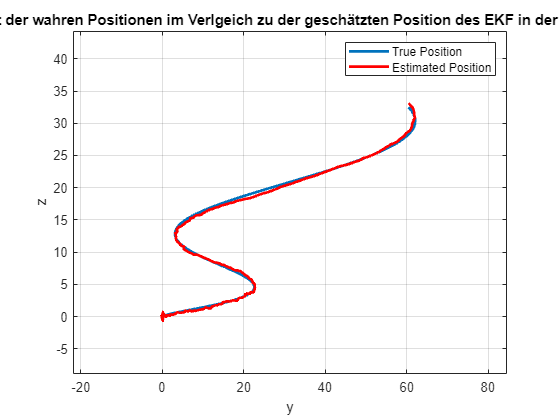


figure(1);
plot(R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot(estimated_position(2, :), estimated_position(3, :), 'r', 'LineWidth', 2);
hold off;
xlabel('y');
ylabel('z');
grid on;
title('3D-Plot der wahren Positionen im Verlgeich zu der geschätzten Position des EKF in der yz Ebene:');
legend('True Position', 'Estimated Position');

function obs = calculate_observations(x_k, pos_radar)
    
    dist_matrix_radar1 = [];
    phi_radar1 = [];
    theta_radar1 = [];

    R_transposed = transpose(x_k);
    for i=1:length(R_transposed(:,1))
        dist_radar1 = norm(R_transposed(1:3) - pos_radar);  % Berechnet den Abstand zwischen der i-ten Zeile von R_transposed und pos_radar
        dist_matrix_radar1 = [dist_matrix_radar1; dist_radar1]; 
        % Berechnung des Elevationswinkels (phi) für Radar 1
        delta_z = R_transposed(3) - pos_radar(3);
        rho = sqrt((R_transposed(1) - pos_radar(1))^2 + (R_transposed(2) - pos_radar(2))^2 + delta_z^2);
        phi_radar1 = [phi_radar1;rad2deg(acos(delta_z/rho))];  % Fügt den Winkel zu phi_radar1 hinzu
        
        % Berechnung des Azimutwinkels (theta) für Radar 1
        delta_x = R_transposed(1) - pos_radar(1);
        delta_y = R_transposed(2) - pos_radar(2);
        theta_radar1 = [theta_radar1; rad2deg(atan2(delta_y, delta_x))];  % Fügt den Winkel zu theta_radar1 hinzu
    end 



    polar_koordinaten_radar1 = [dist_matrix_radar1, theta_radar1, phi_radar1];
    
    obs = transpose(polar_koordinaten_radar1);

end


function H = create_observation_matrix(x_k, pos_radar1, pos_radar2)
    H = zeros(6, 6);
    H(1:3, 1:3) = eye(3);
    H(4:6, 4:6) = eye(3);

    obs_radar1 = calculate_observations(x_k, pos_radar1);
    obs_radar2 = calculate_observations(x_k, pos_radar2);

    % Beobachtung 1 (Abstand zu pos_radar1)
    dxyz = x_k(1:3, 1)' - pos_radar1;
    H(1, 1:3) = dxyz / obs_radar1(1);

    % Beobachtung 2 (Azimutwinkel zu pos_radar1)
    dxy = dxyz(1:2);
    H(2, 1:2) = [-dxy(2), dxy(1)] / norm(dxy)^2;

    % Beobachtung 3 (Elevationswinkel zu pos_radar1)
    H(3, 1:3) = [-dxy(1)*dxyz(3), -dxy(2)*dxyz(3), norm(dxy)^2] / (obs_radar1(3) * norm(dxyz)^3);

    % Beobachtung 4 (Abstand zu pos_radar2)
    dxyz = x_k(1:3, 1)' - pos_radar2;
    H(4, 1:3) = dxyz / obs_radar2(1);

    % Beobachtung 5 (Azimutwinkel zu pos_radar2)
    dxy = dxyz(1:2);
    H(5, 1:2) = [-dxy(2), dxy(1)] / norm(dxy)^2;

    % Beobachtung 6 (Elevationswinkel zu pos_radar2)
    H(6, 1:3) = [-dxy(1)*dxyz(3), -dxy(2)*dxyz(3), norm(dxy)^2] / (obs_radar2(3) * norm(dxyz)^3);
end


function kartesische_koordinaten_radar = get_kartesische_Koordianten(polar_koordinaten_radar)
    
    polar_koordinaten_radar = transpose(polar_koordinaten_radar);
    x_list1 = [];
    y_list1 = [];
    z_list1 = [];
    x_list2 = [];
    y_list2 = [];
    z_list2 = [];
    

    for i = 1:length(polar_koordinaten_radar(:,1))
        % Berechnung der kartesischen Koordinaten für Radar 1
        x_radar1 = polar_koordinaten_radar(i, 1) .* sin(deg2rad(polar_koordinaten_radar(i, 3))) .* cos(deg2rad(polar_koordinaten_radar(i, 2)));
        y_radar1 = polar_koordinaten_radar(i, 1) .* sin(deg2rad(polar_koordinaten_radar(i, 3))) .* sin(deg2rad(polar_koordinaten_radar(i, 2)));
        z_radar1 = polar_koordinaten_radar(i, 1) .* cos(deg2rad(polar_koordinaten_radar(i, 3)));
        x_list1 = [x_list1; x_radar1];
        y_list1 = [y_list1; (y_radar1-10)];
        z_list1 = [z_list1; z_radar1];

        
        % Berechnung der kartesischen Koordinaten für Radar 2
        x_radar2 = polar_koordinaten_radar(i, 4) .* sin(deg2rad(polar_koordinaten_radar(i, 6))) .* cos(deg2rad(polar_koordinaten_radar(i, 5)));
        y_radar2 = polar_koordinaten_radar(i, 4) .* sin(deg2rad(polar_koordinaten_radar(i, 6))) .* sin(deg2rad(polar_koordinaten_radar(i, 5)));
        z_radar2 = polar_koordinaten_radar(i, 4) .* cos(deg2rad(polar_koordinaten_radar(i, 6)));
        x_list2 = [x_list2; (x_radar2 -50)];
        y_list2 = [y_list2; (y_radar2 +30)];
        z_list2 = [z_list2; z_radar2];

    end
    % Kombinieren der kartesischen Koordinaten für Radar 1
    kartesische_koordinaten = [x_list1, y_list1, z_list1, x_list2, y_list2, z_list2];
    kartesische_koordinaten_radar = transpose(kartesische_koordinaten);


end